# LAIIQAToolbox

## Descripción

**Matlab®** **toolbox** para ajustar y graficar los datos de los archivos `.mat` generados del proceso de ozonización en el Laboratorio de Investigación en Ingeniería Química Ambiental (LAIIQA) de ESIQIE - IPN.

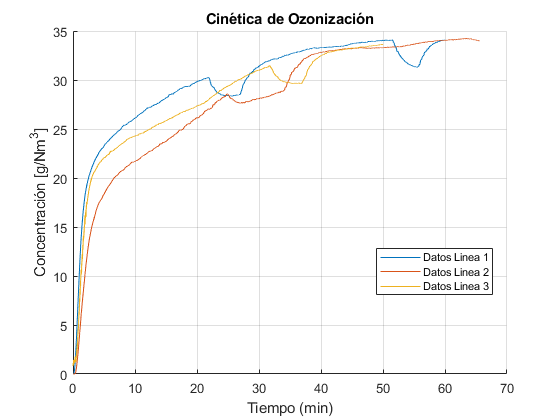

## Requerimientos de Sistema

- MATLAB R2020b o posterior.

- *laiiqatoolbox*

## Instalación

Desde **Matlab**, ir a pestaña  **Home** > **Add-Ons** > **Get Add-Ons**, en el *Add-Ons Explorer* buscar como **laiiqatoolbox**.

## Caracteristicas

- Programación orientada a objetos.

- Grafica datos ajustados (recortados) a una concentración inicial cero (o cercana).

- Acceso a propiedades de grafico: titulo, etiquetas de ejes *x* y *y*, legenda, grosor de línea, etc.

- Conversión de datos de tiempo del eje *x* : `seg`, `min`, `h`.

- Multiselección de archivos para grafcar.

- Acceso a variables de datos crudos (`rawdata`) y ajustados (`fixeddata`).

- Calculo de consumo de ozono.

- Acceso a variables de consumo de ozono (`ozoneresults`).

- Guardado de grafico en varios formatos: `png`, `jpg`, `jpeg`, `pdf`, `eps`, `svg`, `tif`, `fig`.

- Creación de varios objetos gráficos a la vez.

- Posibilidad de ajustar el tiempo total de la cinética con el multiplicador $xk$.

## Propiedades del objeto `laiiqatoolbox`

- `rawdata` : Datos "crudos", sin tratamiento, que contiene las filas de tiempo (1/100 $s$)  y concentración de ozono ($g/m^3$) del archivo `.mat`.

- `fixeddata` : Datos "ajustados", recortados para quitar los primeros datos de estabilización de la concentración de ozono y para comenzar el ozonograma desde una concentración igual o cercana a cero. Convierte los datos de tiempo a minutos por default.

- `title` : Modifica o quita el titulo del gráfico.

- `xlabel` : Modifica los datos de tiempo. **Opciones**: `'seg'` | `'min'` | `'h'`.

- `xk` : Multiplica los valores de tiempo $x$ de cada linea de datos por una constante $k$.

- `xf` : Establece un valor final de tiempo, $x_f$ para cada linea de datos, de acuerdo a las unidades establecidas en  `xlabel`. **Opciones**: `'end'` (default) | <`x>` (cualquier valor de tiempo). Ejemplo: `miobjeto.xf = { 60 'end' 45 ...etc }`. Con `xlabel = 'min'`, `60` y `45` corresponden a minutos.

- `ylabel` : Cambia el titulo del eje *y*.

- `grid` : Activa o desactiva las rejillas del gráfico. **Opciones**: `'on'` (default) `|` `'off'` | `'minor'`.

- `LineWidth` :Cambia el grosor de linea para todas las lineas de datos. Default = `11`.

- `legend` : Cambia o quita la legenda para cada linea de datos. **Opciones**: `{'default'}` (default) | `{ "<nombre de leyenda 1>"  "<nombre de leyenda 2>"  ...etc }`. Ejemplo: `{'default'} `ó `{"Linea 1" "Linea 2" "Linea 3" ...etc }`. `default` pone de leyenda los nombres de archivos abiertos.

- `legendFontSize` : Cambia el tamaño de letra de todas las leyenda. Default = `8`.

- `legendLocation` : Ubicación de la leyenda en el gráfico. **Opciones**: `'best'` (default) | `'south'` | `'east'` | `'west'` | `'northeast'` | ...etc. Ver [documentación](https://la.mathworks.com/help/matlab/ref/matlab.graphics.illustration.legend-properties.html) para más opciones.

- `imageResolution` : Cambia la resolución de los formatos de imgen al guardar con el método `saveplot('nombre.ext')`. Default = `300`.

- `titleInterpreter` : Interprete utilizado para el renderizado del titulo. **Opciones**: `'tex'` (default)  | `'latex'`.

- `labelInterpreter` : Interprete utilizado para el renderizado del titulo de los ejes. **Opciones**: `'tex' (default) | 'latex'`.

- `legendInterpreter` : Interprete utilizado para el renderizado de las leyedas. **Opciones**: `'tex' (default) | 'latex'`.

- `ozoneUnits` : Unidades utilizadas para el cálculo del consumo de ozono. **Opciones**: `'g/L'` (default) | `g/m^3'` | `'g/Nm^3'`.

- `ozoneresults` : Variable que almacena los calculos del consumo de ozono.

## Métodos del objeto `laiiqatoolbox`

- `openfiles` : Abre una ventana de dialogo para selececionar los archivos a graficar.

- `plotfiles` : Procesa los archivos seleccionados y crea el objeto gráfico.

- `ozonecalc` : Procesa los datos de cada archivo y calcula el ozono consumido, residual y total.

- `saveplot` : Guarda el objeto gráfico con el nombre y formato especificado. Ejemplo: `saveplot('nombre.pdf')`.

## Guía de uso

### Creación del objeto

Inicializamos una instancia de objeto de tipo ***laiiqatoolbox***:

% clearvars
% close all
clc
miobjeto1 = laiiqatoolbox

miobjeto1 =   laiiqatoolbox with properties:

              rawdata: []
            fixeddata: []
                title: "Cinética de Ozonización"
               xlabel: 'min'
                   xf: {'end'}
               ylabel: "Concentración [g/L]"
                 grid: 'on'
            LineWidth: 0.5000
               legend: {'default'}
       legendFontSize: 8
       legendLocation: 'best'
      imageResolution: 300
     titleInterpreter: 'tex'
     labelInterpreter: 'tex'
    legendInterpreter: 'tex'
           ozoneUnits: 'g/L'
         ozoneresults: []


### Carga de archivos

Cargamos los archivos *.mat* generados por el ozonograma con el método `openfiles`:

miobjeto1.openfiles

ans =   laiiqatoolbox with properties:

              rawdata: {[2×498709 double]  [2×500280 double]  [2×423437 double]}
            fixeddata: []
                title: "Cinética de Ozonización"
               xlabel: 'min'
                   xf: {'end'  'end'  'end'}
               ylabel: "Concentración [g/L]"
                 grid: 'on'
            LineWidth: 0.5000
               legend: {'default'}
       legendFontSize: 8
       legendLocation: 'best'
      imageResolution: 300
     titleInterpreter: 'tex'
     labelInterpreter: 'tex'
    legendInterpreter: 'tex'
           ozoneUnits: 'g/L'
         ozoneresults: []


### Creación del gráfico

Graficamos los archivos cargados con el método `plotfiles`:

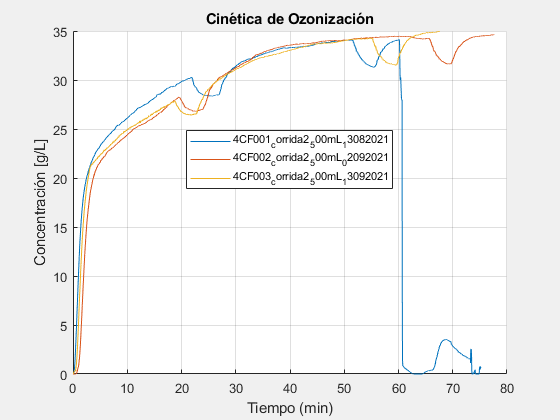

ans =   laiiqatoolbox with properties:

              rawdata: {[2×498709 double]  [2×500280 double]  [2×423437 double]}
            fixeddata: {[2×450938 double]  [2×466141 double]  [2×405324 double]}
                title: "Cinética de Ozonización"
               xlabel: 'min'
                   xf: {'end'  'end'  'end'}
               ylabel: "Concentración [g/L]"
                 grid: 'on'
            LineWidth: 0.5000
               legend: {["4CF001_corrida2_500mL_13082021"]  ["4CF002_corrida2_500mL_02092021"]  ["4CF003_corrida2_500mL_13092021"]}
       legendFontSize: 8
       legendLocation: 'best'
      imageResolution: 300
     titleInterpreter: 'tex'
     labelInterpreter: 'tex'
    legendInterpreter: 'tex'
           ozoneUnits: 'g/L'
         ozoneresults: []


miobjeto1.plotfiles

### Moficación de las propiedades del objeto

Para modificar el titulo del gráfico:

miobjeto1.title = 'Mi Gráfico 1'; % Con ; evitamos mostrar las propiedades del objeto

Para aplicar los cambios echos a las propiedades ejecutamos el método `plotfiles` de nuevo:

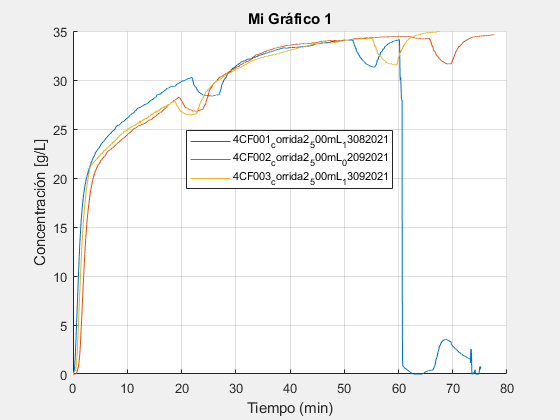

miobjeto1.plotfiles;

Quitamos el titulo del gráfico, cambiamos la etiqueta del eje *y, *desactivamos las gradillas y cambiamos los nombres de las leyendas:

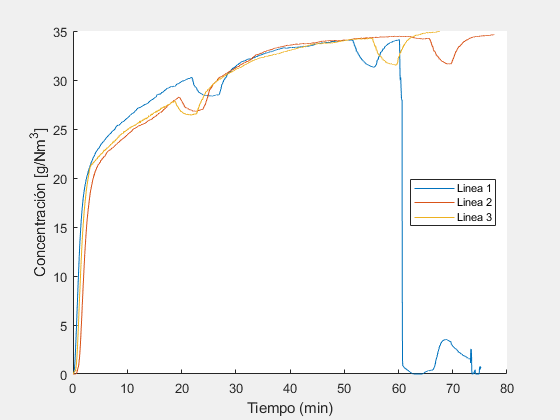

miobjeto1.title = ''; % Quitamos titulo
miobjeto1.ylabel = 'Concentración [g/Nm^3]'; % Cambio de g/L a g/Nm^3
miobjeto1.grid = 'off'; % Desactiva las rejillas
miobjeto1.legend = {'Linea 1' 'Linea 2' 'Linea 3'}; % Renombrado de leyendas
miobjeto1.plotfiles; % Aplicamos los cambios

Como se observa en el gráfico anterior, los datos de la **Linea 1 **terminan abruptamente después del minuto 60, para quitarlos modificamos el valor de $x_{f}$ ($x$ final) de la **Linea 1** con la propiedad `xf:`

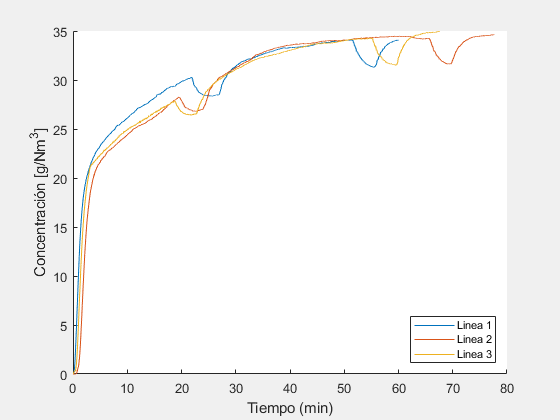

miobjeto1.xlabel = 'min'; % Establecemos las unidades de tiempo
miobjeto1.xf{1} = 60; % Asignamos un valor de xf = 60 minutos
miobjeto1.plotfiles; % Aplicamos los cambios

Cambiamos el valor de `xf` de la **Linea 3**:

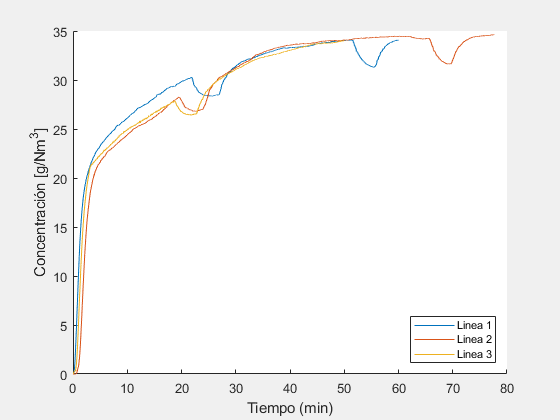

miobjeto1.xf{3} = 50; % Asignamos un vamor xf = 50 minutos
miobjeto1.plotfiles; % Aplicamos los cambiamos

Para cambiar los 3 valores de `xf `al mismo tiempo:

miobjeto1.xf = {60 'end' 50}; % Asignamos un valor de 60 min 
% a la Linea 1, todos los datos a la Linea 2 y 
% 50 min a la Linea 3
miobjeto1.plotfiles; % Aplicamos los cambios

### Calculo del consumo de ozono

Una vez ejecutados los métodos `openfiles` y `plotfiles` se puede ejecutar el método `ozonecalc`:

miobjeto1.ozonecalc;

Para Linea 1:
    Consumido: 0.27064 g/L
    Residual: 1.775 g/L
    Total: 2.0456 g/L en 60 min


Para Linea 2:
    Consumido: 0.35836 g/L
    Residual: 2.3315 g/L
    Total: 2.6899 g/L en 77.69 min


Para Linea 3:
    Consumido: 0.29924 g/L
    Residual: 1.4031 g/L
    Total: 1.7024 g/L en 50 min




### Exportar imagen del gráfico

Para guardar la imagen del objeto gráfico, utilizamos el método `saveplot('nombre.ext'):`

miobjeto1.imageResolution = 600; % Resolución de imagen, default = 300
miobjeto1.saveplot('ozonograma1.png'); % Nombre y extensión del archivo

Para guardar en formato vectorial (*pdf, eps, svg*) no es necesario modificar la resolución:

miobjeto1.saveplot('ozonograma1.pdf');